Data

humidity = [20 30 40 50]'

humidity =     20
    30
    40
    50


conductivity = [8 23 28 34]'

conductivity =      8
    23
    28
    34



xdata = (humidity-35)/5;
xdata = humidity;
ydata = conductivity;
one = ones(size(xdata));

% for visualization
vx = linspace(xdata(1), xdata(end));
vx = (vx-mean(xdata))*1.5+mean(xdata);

figure
hold on
plot(xdata, ydata, 'o');
xlabel("humidity");
ylabel("conductivity");

Linear fit

A = [one xdata];
c = (A'*A)\(A'*ydata);
vy = c(1) + c(2)*vx;
plot(vx, vy, '--');

Quadratic fit

A = [one xdata xdata.^2];
c = (A'*A)\(A'*ydata);
vy = c(1) + c(2)*vx + c(3)*vx.^2;
plot(vx, vy, '--');

Cubic fit

A = [one xdata xdata.^2 xdata.^3];
c = (A'*A)\(A'*ydata);
vy = c(1) + c(2)*vx + c(3)*vx.^2 + c(4)*vx.^3;
plot(vx, vy, '--');

Sqrt fit

A = [sqrt(xdata) one];
c = (A'*A)\(A'*ydata);
vy = c(1)*sqrt(vx) + c(2);
plot(vx, vy, '--');

Exponential fit

A = [one xdata];
b = log(ydata);
c = (A'*A)\(A'*b);
vy = exp(c(1)) * exp(c(2)).^vx;
plot(vx, vy, '--');

Logarithmic fit

A = [one log(xdata)];
b = ydata;
c = (A'*A)\(A'*b);
vy = c(1)+c(2)*log(vx);
plot(vx, vy, '--');

Sine fit

A = [sin(xdata) cos(xdata) xdata one];
b = ydata;
c = (A'*A)\(A'*b);
a = hypot(c(1), c(2));
b = atan2(c(2), c(1));
vy = a*sin(vx+b)+c(3)*vx+c(4);
plot(vx, vy, '--');

Legend

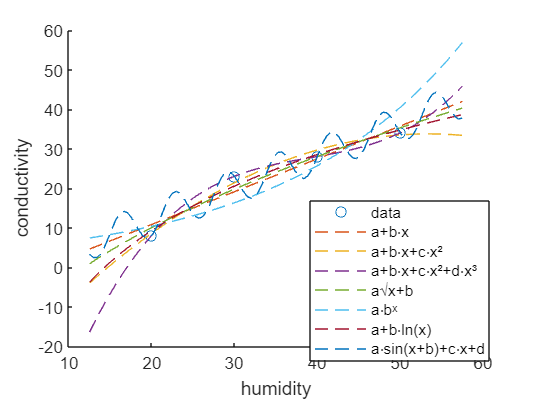

legend("data", "a+b⋅x", "a+b⋅x+c⋅x²", "a+b⋅x+c⋅x²+d⋅x³", ...
    "a√x+b", "a⋅bˣ", "a+b⋅ln(x)", "a⋅sin(x+b)+c⋅x+d");

legend("Position",[0.6,0.2,0.3,0.2])

Best interpolation: cubic

Best extrapolation: linear (or quadratic)